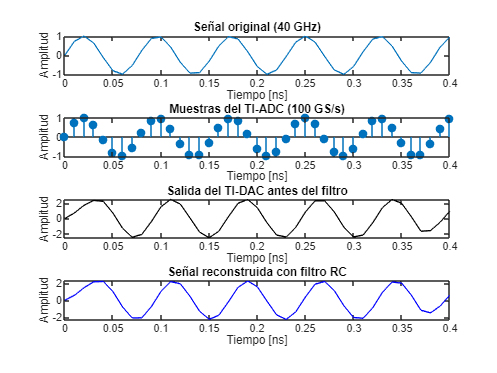

clc; clear; close all;

%% Parámetros generales
Fs_signal = 100e9;             % Frecuencia de simulación (200 GS/s)
f = 13e9;                      % Frecuencia de la señal original (40 GHz)
t_total = 0.4e-9;              % Duración total: 0.4 ns
t = 0:1/Fs_signal:t_total;     % Tiempo continuo

%% Señal original
x = sin(2*pi*f*t);             % Señal senoidal analógica

%% Parámetros TI-ADC
M = 4;
Fs_adc = 25e9;
Fs_total = M * Fs_adc;
Ts_total = 1 / Fs_total;
t_adc = 0:Ts_total:t_total;

% Simular muestreo
x_ti_adc = zeros(1, length(t_adc));
t_sub = cell(1, M);
x_sub = cell(1, M);

for m = 1:M
    t_m = t_adc(m:M:end);
    x_m = sin(2*pi*f*t_m);
    t_sub{m} = t_m;
    x_sub{m} = x_m;
    x_ti_adc(m:M:end) = x_m;
end

%% TI-DAC con retención ZOH
x_out_sub = zeros(M, length(t));
for m = 1:M
    x_out_sub(m, :) = interp1(t_sub{m}, x_sub{m}, t, 'previous', 0);
end
x_out_dac = sum(x_out_sub, 1);

%% Filtro RC (respuesta exponencial)
RC = 1/(2*pi*60e9);            % Corte aproximado 60 GHz
dt = 1/Fs_signal;
alpha = dt / (RC + dt);        % Coeficiente para filtro IIR

x_rc = zeros(size(x_out_dac));
for n = 2:length(x_out_dac)
    x_rc(n) = alpha * x_out_dac(n) + (1 - alpha) * x_rc(n-1);  % Filtro RC discreto
end

%% Gráficas
figure;

subplot(4,1,1);
plot(t*1e9, x);
title('Señal original (40 GHz)');
xlabel('Tiempo [ns]'); ylabel('Amplitud');
xlim([0 t_total*1e9]);

subplot(4,1,2);
stem(t_adc*1e9, x_ti_adc, 'filled');
title('Muestras del TI-ADC (100 GS/s)');
xlabel('Tiempo [ns]'); ylabel('Amplitud');
xlim([0 t_total*1e9]);

subplot(4,1,3);
plot(t*1e9, x_out_dac, 'k');
title('Salida del TI-DAC antes del filtro');
xlabel('Tiempo [ns]'); ylabel('Amplitud');
xlim([0 t_total*1e9]);

subplot(4,1,4);
plot(t*1e9, x_rc, 'b');
title('Señal reconstruida con filtro RC');
xlabel('Tiempo [ns]'); ylabel('Amplitud');
xlim([0 t_total*1e9]);